# O’Rourke vs Tanner Values

## Radii and Velocity

radius_values = [ ...
    repmat(0.0113226119, 1, 16), ...
    repmat(0.0001132261,  1, 16), ...
    repmat(0.0000011323,  1, 16)  ...
]; %m, radii needed to achieve Oh values
velocity_values = [ ...
    1.455902561, 1.783109195, 2.058957148, 2.301984072, 3.255497096, ...
    4.603968145, 5.638686374, 6.510994191, 7.279512806, 10.29478574, ...
    14.55902561,  17.83109195, 20.58957148, 23.01984072, 32.55497096, ...
    46.03968145,  14.55902561, 17.83109195, 20.58957148, 23.01984072, ...
    32.55497096,  46.03968145, 56.38686374, 65.10994191, 72.79512806, ...
    102.9478574,  145.5902561,  178.3109195, 205.8957148, 230.1984072, ...
    325.5497096,  460.3968145,  145.5902561, 178.3109195, 205.8957148, ...
    230.1984072,  325.5497096,  460.3968145, 563.8686374, 651.0994191, ...
    727.9512806,  1029.478574,  1455.902561, 1783.109195, 2058.957148, ...
    2301.984072,  3255.497096,  4603.968145 ...
]; %m/s, velocity values

### O'Rourke

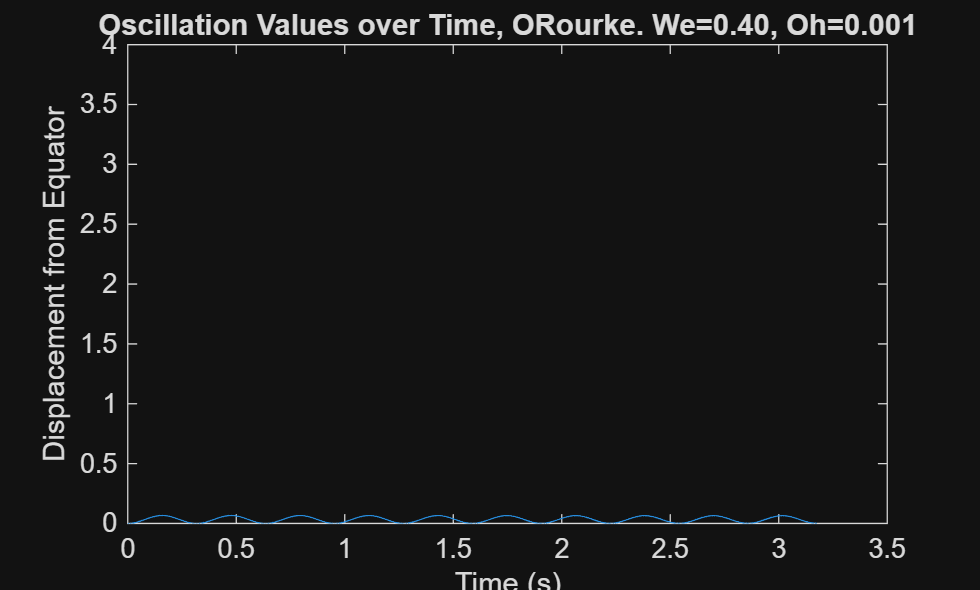

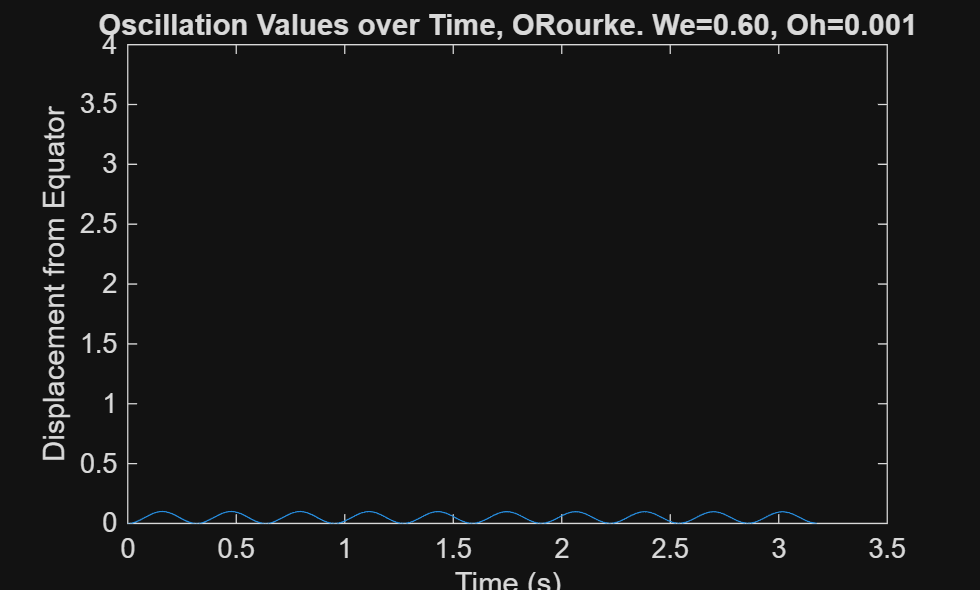

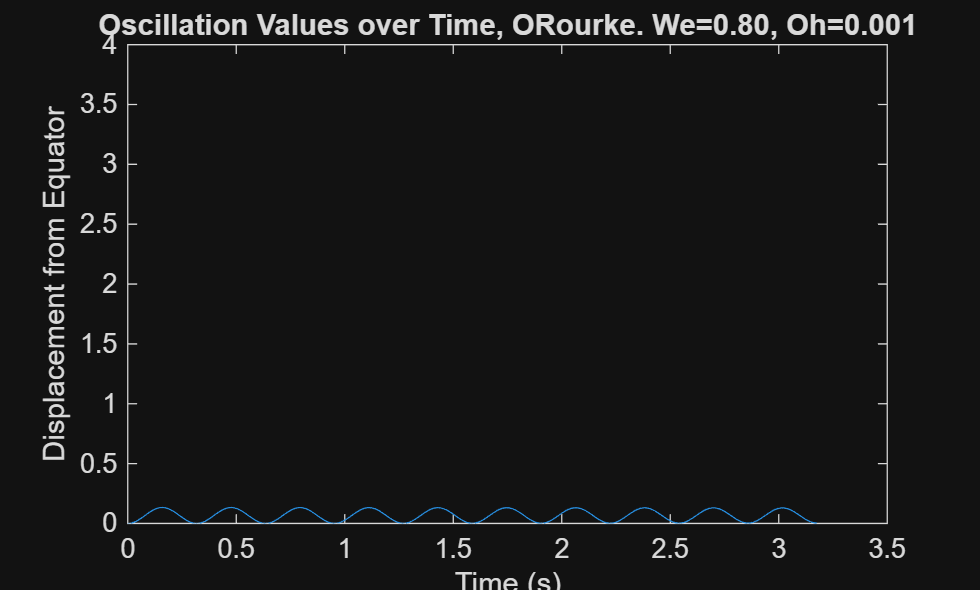

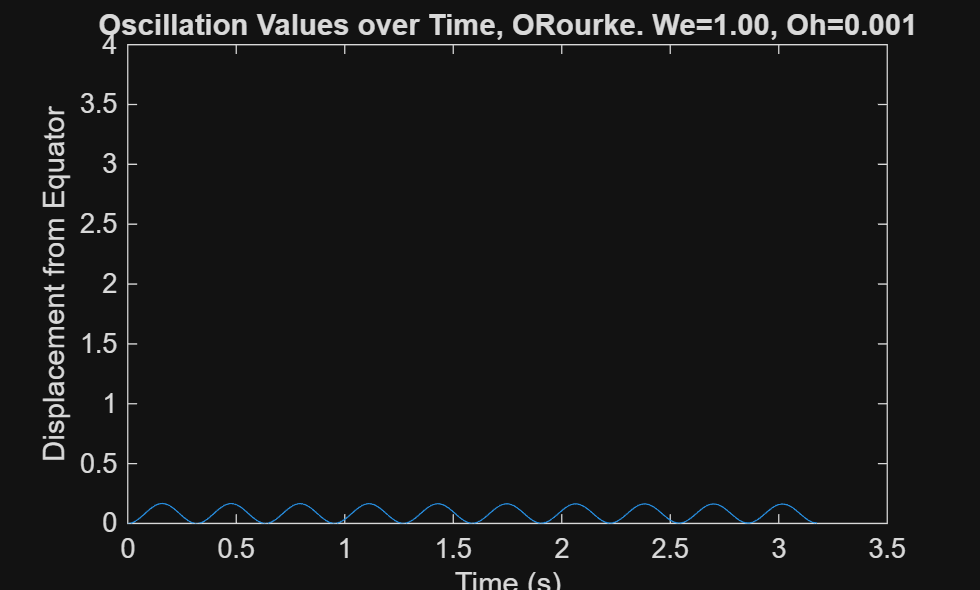

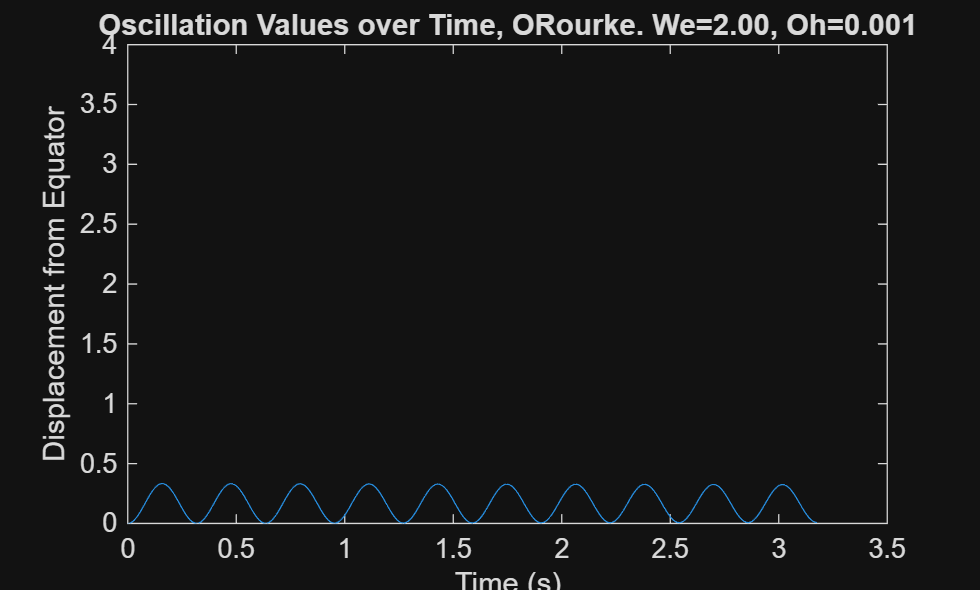

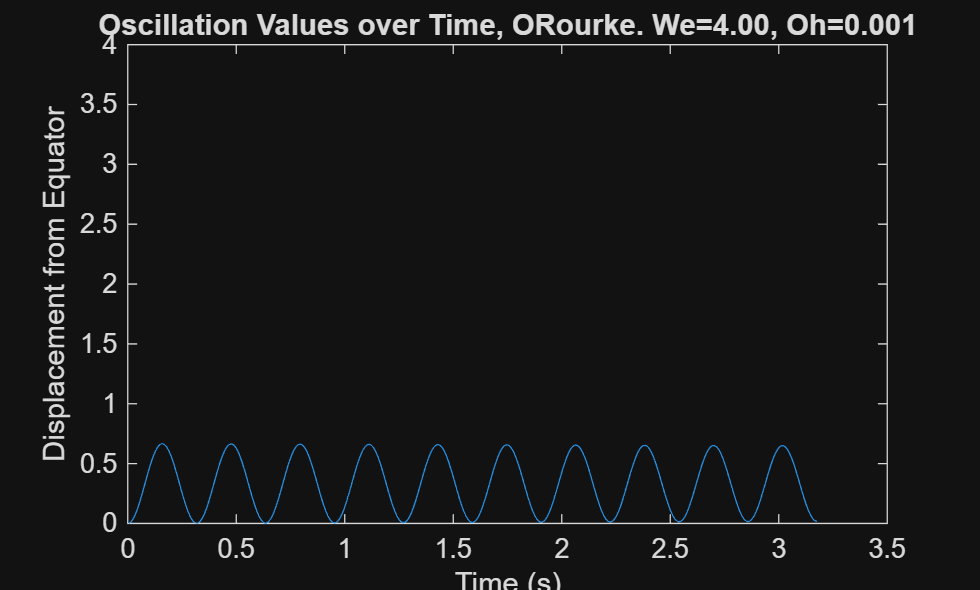

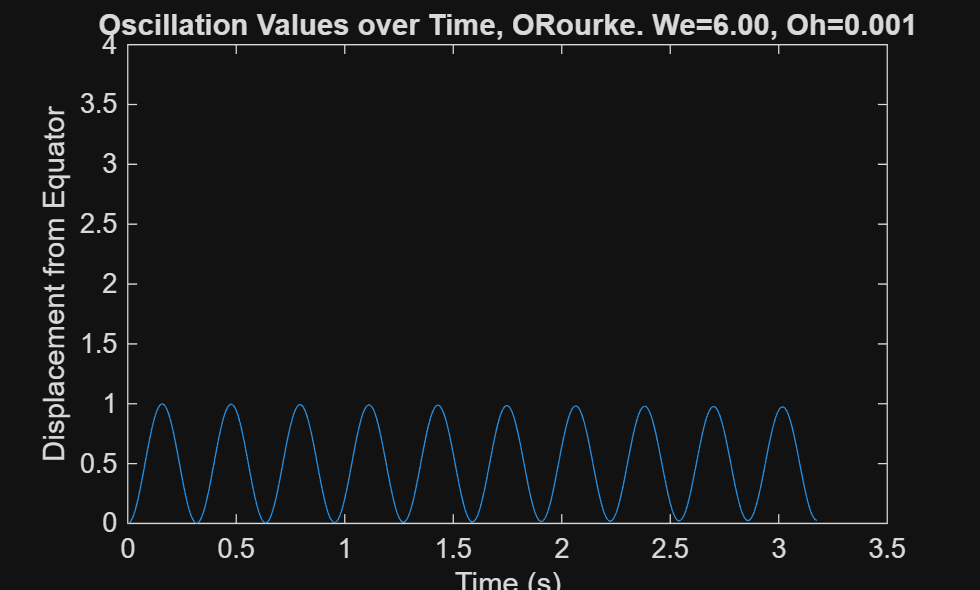

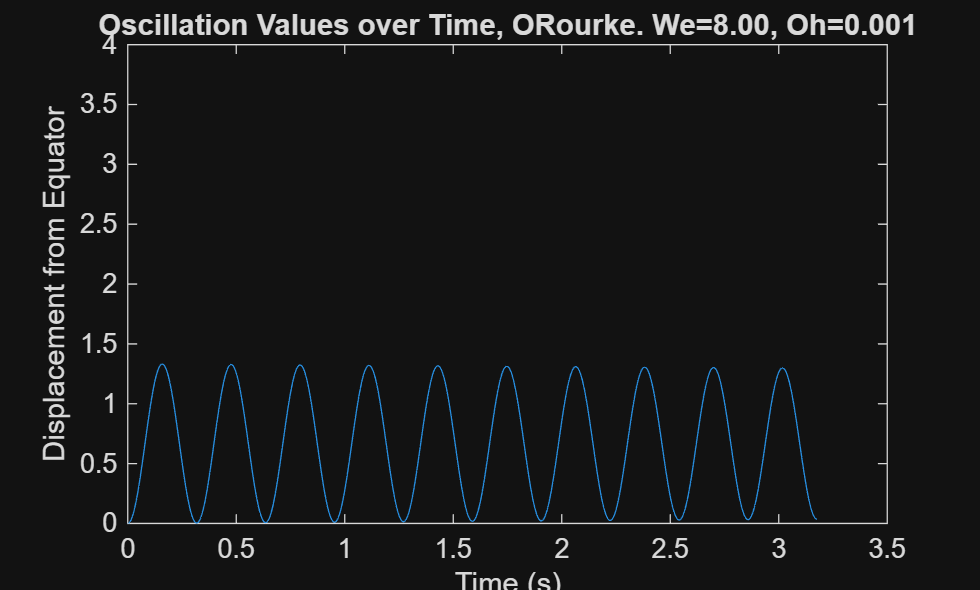

max_y_val_or = zeros(length(radius_values)); %array for max normalized displacement from sphere
We_or = zeros(length(radius_values)); %array for all the Weber numbers
regimes_Or = zeros(length(radius_values),1);

for k = 1:length(radius_values)
    %All constants and initial conditions are defined here
    y_0 = 0; %inital displacement (starts as a perfect sphere)
    y_dot_0 = 0; %initial displacement velocity 
    
    Cf = 1/3; %force constant
    Ck = 8; %linear constant
    Cd = 5; %damping constant
    Cb = 1/2; %breakup constant
    
    %These values may be changed:
    rho_g = 1.18; %kg/m^3, density of gaseous ethylene
    rho_l = 997; %kg/m^3, density of liquid
    r = radius_values(k); %m, radius of droplet (~.2mm) **
    sigma = 0.0708; %kg/s^2, surface tension 
    u = velocity_values(k); %m/s, velocity

    mu_l = 0.000894; %Pa*s, the dynamic viscocity of Jet A
    t_bu = 8*sqrt(rho_l*r/(rho_g*u)); %breakup time of particle, breakup only happens when t > t_bu
    
    Oh = mu_l / ((rho_l*r*sigma)^(1/2)); %Ohnesorge number, from Faeth et al pg 636, between 10^-4 and 10^-2 for oscillatory behaviour
    We = rho_g*(u^2)*r/sigma; %Weber number, eq 4 %We bound to 2-9 for oscillatory behaviour
    We_or(k) = We; 
    
    omega = sqrt(Ck*sigma/(rho_l*r^3)); %oscillation frequency, eq 4

    duration = 10 * (2*pi/omega);  %seconds, the time we want to watch this particle
    len = 1000; %length of time vector
    dt = linspace(0,duration,len); %s, time vector
    timestep = dt(2)-dt(1); %timestep, in seconds

    t_d = (2/Cd) * (rho_l*r^2/mu_l); %under equation 4
    
    %define size of array beforehand
    y_vals = zeros(1,len); %array for normalized displacements over time
    y_dot_vals = zeros(1,len); %array for normalized change in displacement over time
    
    y_vals(1) = y_0;
    y_dot_vals(1) = y_dot_0;
    volume = (4/3)*pi*r^3; %constant
    
    breakup_time = 0; %Breakup time
    breakup_iteration = 0;
    
    for i = 1:(length(dt)-1)
        %Defining some terms which show up frequently
        s = sin(omega*timestep);
        c = cos(omega*timestep);
        ex = exp(-timestep/t_d);
        y_We12 = y_vals(i) - We/12;
    
        y_vals(i+1) = (We/12) + ex*( (y_We12)*c + (1/omega)*(y_dot_vals(i) + (y_We12/t_d))*s );
        y_dot_vals(i+1) = (((We/12) - y_vals(i+1))/t_d) + omega*ex*( (1/omega)*(y_dot_vals(i) + (y_We12/t_d) )*c - (y_We12)*s );
    
        if (y_vals(i+1)+(We/12) > 1) && (dt(i) > t_bu)
            breakup_time = pi*sqrt( (rho_l*r^3)/80 ); %half period of the fundamnetal mode of oscillation in this paper
            breakup_iteration = i;
            num_drops = 13; %13 new drops
    
            r_new = ((volume/num_drops)*(3/4)*(1/pi))^(1/3); %New droplet radius
            Cv = 1;
            spray_angle = 2 * atan( Cv*(sqrt(3)/3))*(sqrt(rho_g/rho_l) ); %Spray angle measured from drop velocity vector, eq 16
            vel_new = abs(Cv*Cb*r*y_dot_vals(i)); %Eq 14, new droplet normal velocities
    
            b = sqrt( (r^3) / (r - (y_vals(i))*r)); %radius of the zy plane circle
    
            for j = 1:num_drops
                drop_angle = 2*pi*j / num_drops;
    
                new_ypos(j) = b * sin(drop_angle); %initial y pos
                new_zpos(j) = b * cos(drop_angle); %inital z pos
    
                new_xvel(j) = vel_new*cos(spray_angle); %x velocity, a constant
                new_yvel(j) = vel_new*sin(spray_angle)*sin(drop_angle); %y velocity
                new_zvel(j) = vel_new*sin(spray_angle)*cos(drop_angle); %z velocity
            end
    
            break;
        end
    end

    pks = findpeaks(y_vals);
    if max(y_vals) <= 0.1
        regimes_Or(k) = 'A'; %no deformation
    elseif(length(pks) > 2) && (max(y_vals)+(We/12) <= 1) && (pks(end)/2 < 0.1)%%(pks(end)/pks(1) %We < bound_C 
        regimes_Or(k) = 'B'; %non osc deformation, the final value is <0.1
    elseif max(y_vals)+(We/12) <= 1
        regimes_Or(k) = 'C'; %oscillatory deformation
    else
        regimes_Or(k) = 'D'; %Bag breakup
    end
    
    %Plotting the y values
    figure;
    plot(dt,y_vals);
    hold on;
    title(sprintf('Oscillation Values over Time, ORourke. We=%.2f, Oh=%.3f', We, Oh))
    xlabel('Time (s)')
    ylabel('Displacement from Equator')
    max_y_val_or(k) = max(y_vals);
    if max_y_val_or(k) < 4
        ylim([0 4]);
    else
        ylim([0 70]);
    end
    hold off;
end

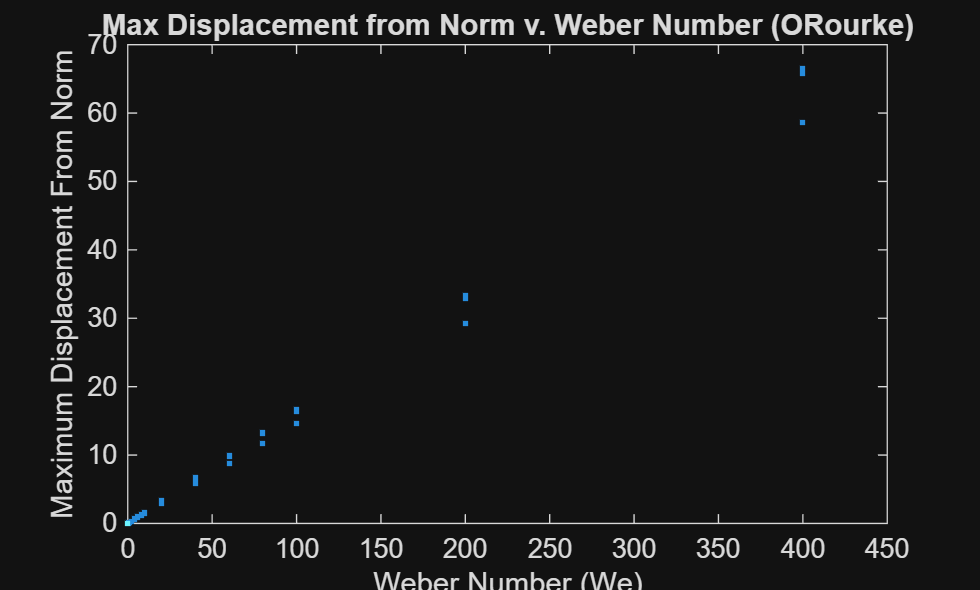



plot(We_or, max_y_val_or, '.');
hold on;
title('Max Displacement from Norm v. Weber Number (ORourke)')
xlabel('Weber Number (We)')
ylabel('Maximum Displacement From Norm')

## Tanner, 2003

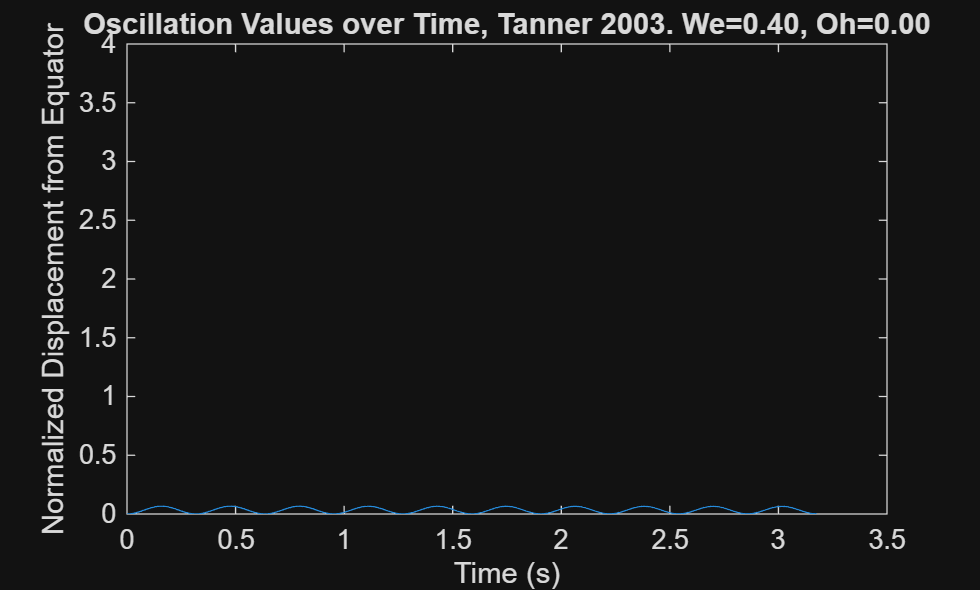

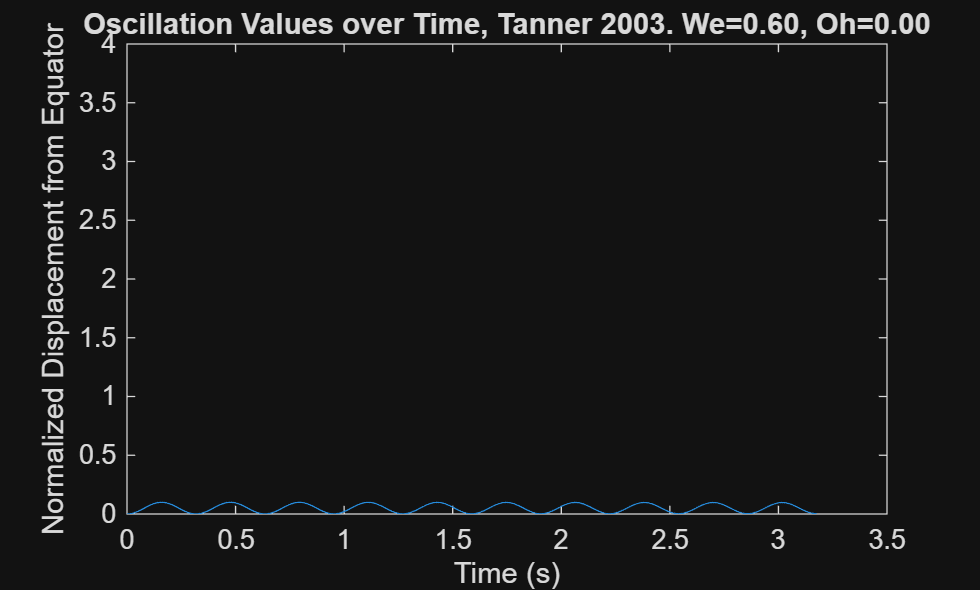

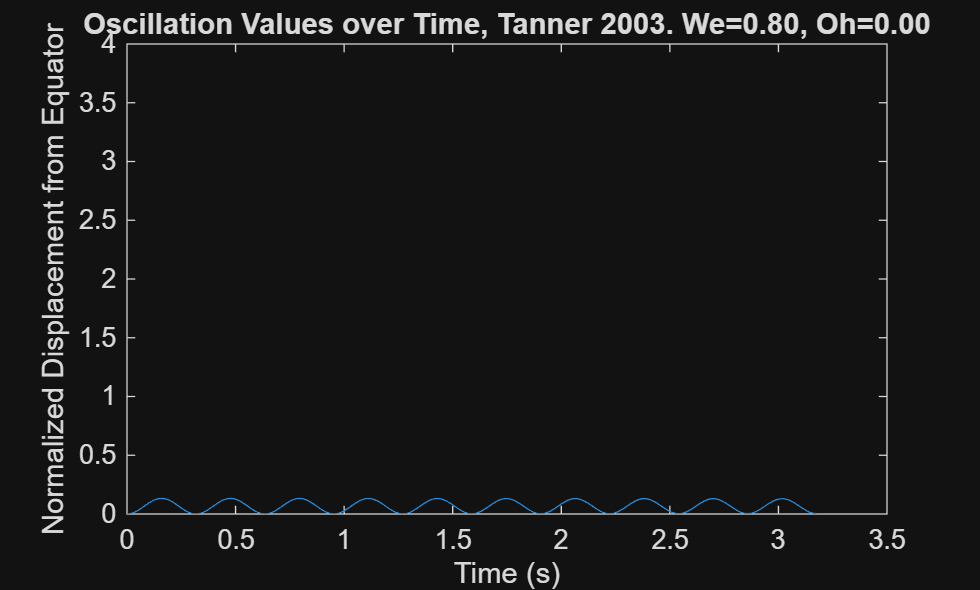

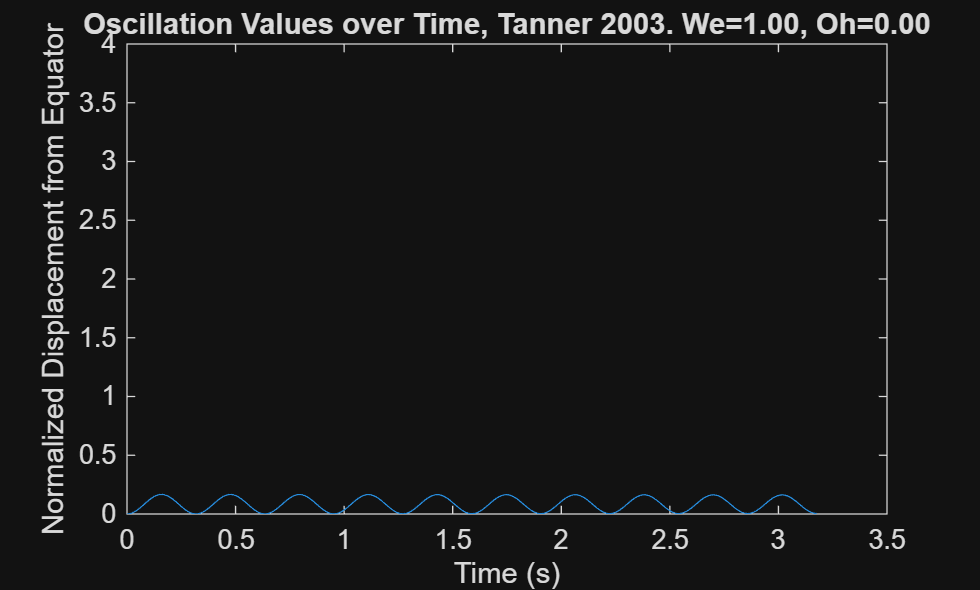

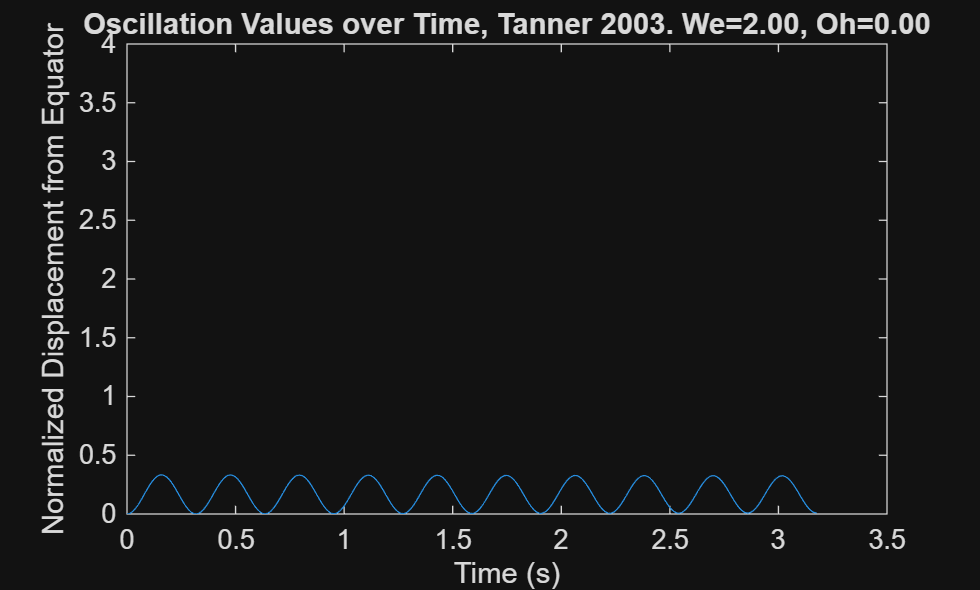

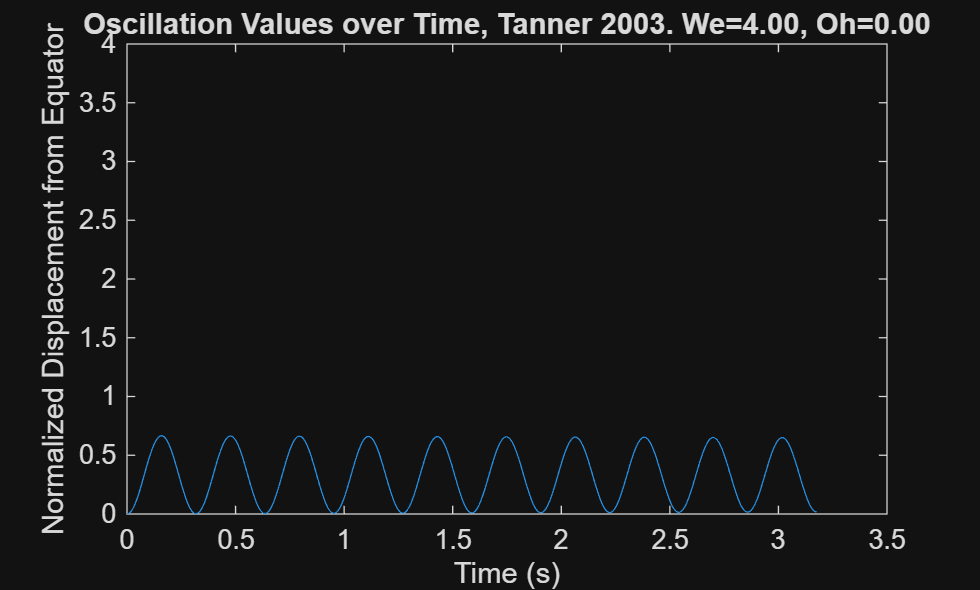

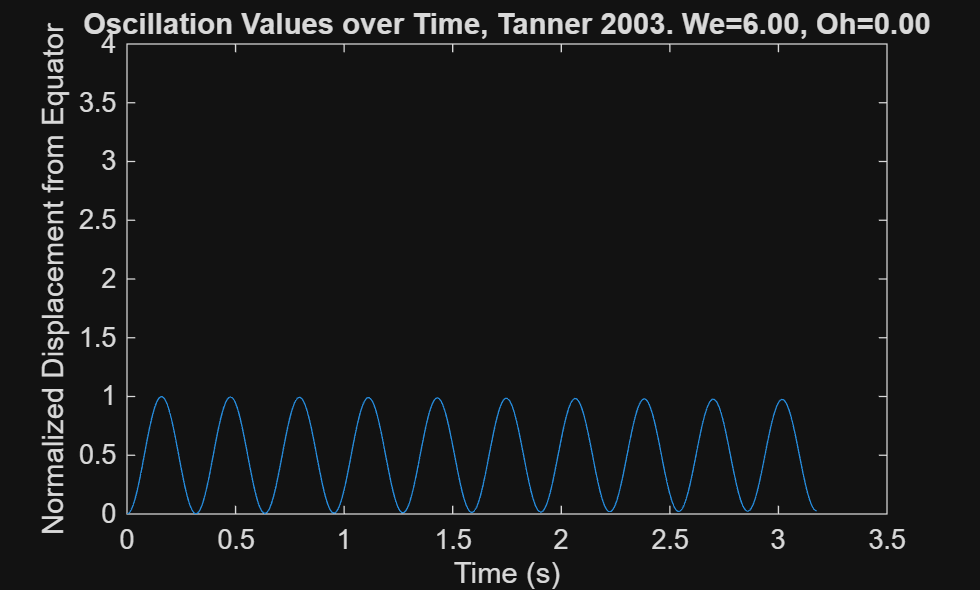

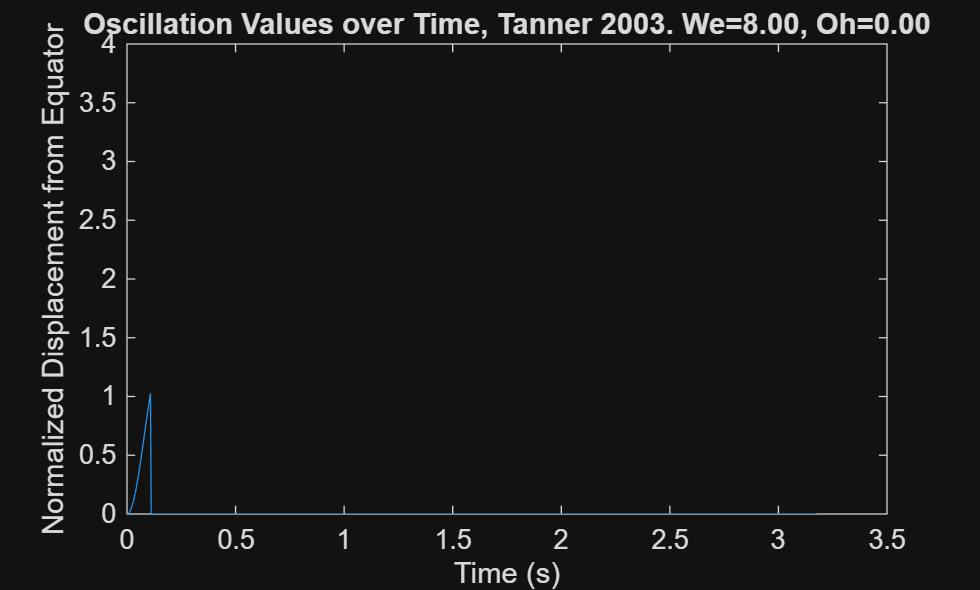

max_y_val_tanner = zeros(length(radius_values)); %array for max normalized displacement from sphere
We_tanner = zeros(length(radius_values)); %array for all the Weber numbers
regimes_Tan = zeros(length(radius_values),1);
ratios = zeros(length(radius_values),1);
zeta = zeros(length(radius_values),1);

for k = 1:length(radius_values)
    %These values may be changed:
    rho_g = 1.18; %kg/m^3, density of gaseous ethylene
    rho_l = 997; %kg/m^3, density of liquid
    parent_r = radius_values(k); %m, radius of droplet (~.2mm) **
    parent_vol = (4/3)*pi*(parent_r^3);
    sigma = 0.0708; %kg/s^2, surface tension 
    u = velocity_values(k); %m/s, velocity
    mu_l = 0.000894; %Pa*s, the dynamic viscocity of Jet A
    mu_g = 0.00185; %air viscosity, may change as a function of mach number (for Re)
    
    Oh = mu_l / ((rho_l*parent_r*sigma)^(1/2)); %Ohnesorge number, from Faeth et al pg 636, between 10^-4 and 10^-2 for oscillatory behaviour
    We =  rho_g*(u^2)*parent_r/sigma; %Weber number, eq 4
    We_tanner(k) = We;

    Re = 2*rho_g*parent_r*u/mu_g;
    
    volume = (4/3)*pi*parent_r^3; %a constant
    
    % Old implementation: assumes inital considitions are both 0. No time Marching. 
    const1 = 5*mu_l/(rho_l*parent_r^2); 
    const2 = 8*sigma / (rho_l*parent_r^3);
    const3 = 2*rho_g*u^2 / (3*rho_l*parent_r^2);
    
    omega = sqrt(const2 - const1^2/4);

    duration = 10 * (2*pi/omega);  %seconds, the time we want to watch this particle
    len = 1000; %length of time vector
    dt = linspace(0,duration,len); %s, time vector
    timestep = dt(2)-dt(1); %timestep, in seconds

    y_vals = (const3/const2)*(1 - exp(-const1*dt/2).*(cos(omega*dt) + (const1/(2*omega))*sin(omega*dt)));

    C_lambda = 5.5; %estimate from tanner paper
    d_0 = 0.15 * 1/1000; %0.15mm, from the table 2 tuning constant
    t_bu = C_lambda * d_0 * sqrt(rho_l/rho_g) / u;
    We_crit = 6;
    We_bs = 80;
    We_sc = 350;
    
    for i = 1:len
        if (y_vals(i) >= 1) && (const2 - ((const1^2)/4) > 0) && (dt(i) >= t_bu)
            breakup_iteration = i;
            
            Omega = sqrt( (8*sigma/(rho_l*(parent_r^3))) - (25*(mu_l^2)/(4*(rho_l^2)*(parent_r^4))) );
            K_br = 0;
            k1 = 0.05; %tuned from CAB model in paper
            k2 = k1 / sqrt(We_bs); %calculated for continuity at We_bs
            k3 = k2 / (We_sc^(1/4)); %calculated for continuity at We_sc
            %Define K_br from equation 3
            if We <= We_bs
                K_br = k1 * Omega; %Bag breakup
                regimes_Tan(k) = 'D';
            elseif We <= We_sc
                K_br = k2 * Omega * sqrt(We); %Stripping breakup
                regimes_Tan(k) = 'E';
            else
                K_br = k3 * Omega * (We^(3/4)); %Catastrophic breakup
                regimes_Tan(k) = 'F';
            end
            
            min_radius = 1e-8; %10 nanometers as a safety floor
            product_r = parent_r * exp(-K_br*dt(i)); %Product drop radius, eq 4
            product_r = max(product_r, min_radius); %grab the larger of the two
            product_vol = (4/3)*pi*(product_r^3);
            num_drops = round(parent_vol / product_vol);
            if num_drops > 1e6
                num_drops = 1e6; %cap at 1 mil drops per parent
            end
    
            C_D = 0.44; %Schiller-Naumann correlation for CD of spherical bodies
            if Re < 1
                C_D = 24/Re;
            elseif Re < 1000
                C_D = 24/Re*(1 + 0.15*Re^0.687);
            end
            r_32 = (parent_r^3) / (product_r^2); %right above eq 7
            term = (5*C_D/4) + ((18*(1-(parent_r/r_32)))/We);
            if term < 0
                %term = 0; %if negative, then parent < product i.e. parent didn't fully breakup
                %continue
                term = -term;
            end
            A = sqrt(term); %equation 8
            spray_angle = atan(A); %Spray angle measured from drop velocity vector
            vel_new = u * A; %Eq 5, new droplet normal velocities
            
            den = parent_r - y_vals(i)*parent_r/2;
            den = max(den, 1e-12); %gaurd or else den --> 0 as y(i) --> 2 and b will --> infinity
            b = sqrt(parent_r^3 / den); %radius of the zy plane circle
            
            %preallocating the variables
            new_ypos = zeros(1,num_drops);
            new_zpos = zeros(1,num_drops);
            new_xvel = zeros(1,num_drops);
            new_yvel = zeros(1,num_drops);
            new_zvel = zeros(1,num_drops);
            for j = 1:num_drops
                drop_angle = 2*pi*j / num_drops;
            
                new_ypos(j) = b * sin(drop_angle); %initial y pos
                new_zpos(j) = b * cos(drop_angle); %inital z pos
            
                new_xvel(j) = vel_new*cos(spray_angle); %x velocity, a constant
                new_yvel(j) = vel_new*sin(spray_angle)*sin(drop_angle); %y velocity
                new_zvel(j) = vel_new*sin(spray_angle)*cos(drop_angle); %z velocity
            end
    
            y_vals(i+1:end) = 0;
            break;
            end
       
        
    end

    % K_prime = 0.16; 
    % density_ratio = rho_g / rho_l;
    % calc_bound = @(We_cr, Oh_val) (We_cr / 4) * (1 + 4*K_prime*(We_cr^-0.5) * sqrt(density_ratio) * Oh_val);
    % bound_B = calc_bound(1.0, Oh); 
    % bound_C = calc_bound(3.0, Oh);
    % bound_D = calc_bound(13.0, Oh);
    % 
    % zeta(k) = bound_C;

    pks = findpeaks(y_vals);
    if max(y_vals) <= 0.1
        regimes_Tan(k) = 'A'; %no deformation
    elseif(length(pks) > 2) && (max(y_vals) <= 1) && (pks(end)/2 < 0.1)%%(pks(end)/pks(1) %We < bound_C 
        regimes_Tan(k) = 'B'; %non osc deformation, the final value is <0.1
        %ratios(k) = pks(end)/pks(1);
    elseif max(y_vals) <= 1
        regimes_Tan(k) = 'C'; %oscillatory deformation
        %ratios(k) = pks(end)/pks(1);
    else%if max(y_vals) >= 1
        %Cases for when it will eventually breakup (ymax>1) but hasn't
        %reached t_bu
        if We <= We_bs
            regimes_Tan(k) = 'D'; %Bag breakup
        elseif We <= We_sc
            regimes_Tan(k) = 'E'; %Stripping breakup
        else
            regimes_Tan(k) = 'F'; %Catastrophic breakup
        end
end
    
    %Plotting the y values
    figure;
    plot(dt,y_vals);
    hold on;
    title(sprintf('Oscillation Values over Time, Tanner 2003. We=%.2f, Oh=%.2f', We, Oh))
    xlabel('Time (s)')
    ylabel('Normalized Displacement from Equator') %y = 2x/a
    max_y_val_tanner(k) = max(y_vals);
    if max_y_val_tanner(k) < 4
        ylim([0 4]);
    else
        ylim([0 70]);
    end
    hold off;
end

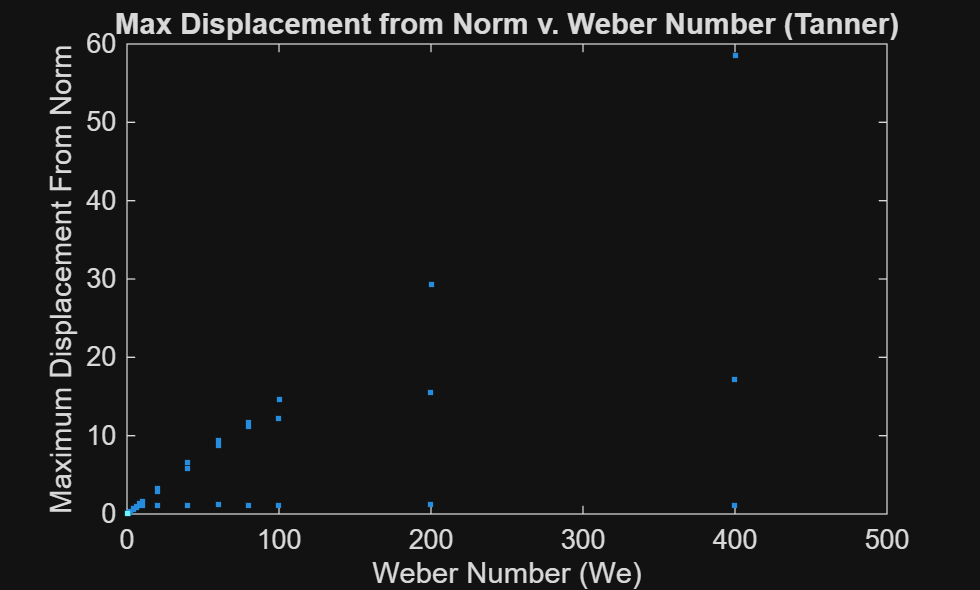


plot(We_tanner, max_y_val_tanner, '.');
hold on;
title('Max Displacement from Norm v. Weber Number (Tanner)')
xlabel('Weber Number (We)')
ylabel('Maximum Displacement From Norm')


char(regimes_Tan)

ans = 48×1 char array
    'A'
    'A'
    'B'
    'B'
    'C'
    'C'
    'C'
    'D'
    'D'
    'D'
    'D'
    'D'
    'E'
    'E'
    'E'
    'F'
    'A'
    'A'
    'B'
    'B'
    'C'
    'C'
    'C'
    'D'
    'D'
    'D'
    'D'
    'D'
    'D'
    'E'
    'E'
    'F'
    'A'
    'A'
    'B'
    'B'
    'B'
    'C'
    'C'
    'D'
    'D'
    'D'
    'D'
    'D'
    'E'
    'E'
    'E'
    'F'


ratios

ratios =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


zeta

zeta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
